1.(b) Plot a Lyapunov function using MATLAB

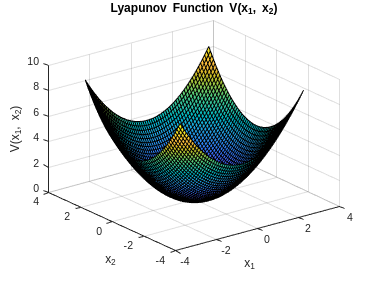

% Define the grid
[x1, x2] = meshgrid(-3:0.1:3, -3:0.1:3);

% Lyapunov function
V = 0.5 * (x1.^2 + x2.^2);

% Plot
figure;
surf(x1, x2, V);
xlabel('x_1');
ylabel('x_2');
zlabel('V(x_1, x_2)');
title('Lyapunov Function V(x_1, x_2)');
grid on;

1.(c) Plot state trajectories of a dynamical system near the origin using MATLAB

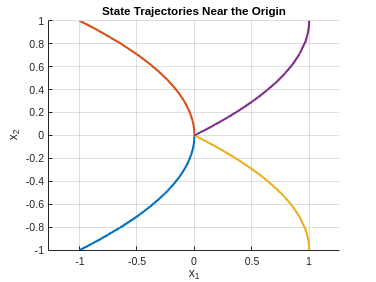

% Define the system dynamics
f = @(t, x) [-x(1) + x(2)^2; -x(2)];

% Time span
tspan = [0 10];

% Initial conditions (near origin)
initial_conditions = [-1 -1; -1 1; 1 -1; 1 1];

% Plot phase portrait
figure; hold on;
for i = 1:size(initial_conditions,1)
    [t, x] = ode45(f, tspan, initial_conditions(i, :)');
    plot(x(:,1), x(:,2), 'LineWidth', 2);
end
xlabel('x_1'); ylabel('x_2');
title('State Trajectories Near the Origin');
grid on;
axis equal;

2.(e) Plot a Lyapunov function using MATLAB

% Define the grid
[x1, x2] = meshgrid(-3:0.1:3, -3:0.1:3);

% Lyapunov function
V = 0.5 * (x1.^2 + x2.^2);

% Plot
figure;
surf(x1, x2, V);
xlabel('x_1'); ylabel('x_2'); zlabel('V(x_1, x_2)');
title('Lyapunov Function V(x_1, x_2)');
grid on;

2.(f) Plot state trajectories of a dynamical system near the origin using MATLAB

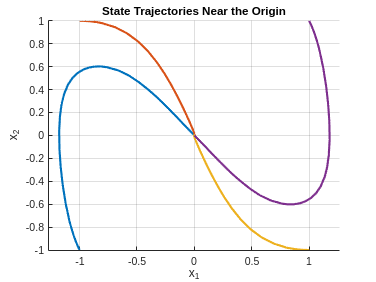

% Define the system dynamics
f = @(t, x) [x(2);
             -x(1) - x(2) - (2*x(2) + x(1))*(1 - x(2)^2)];

% Time span
tspan = [0 20];

% Initial conditions
initial_conditions = [-1 -1; -1 1; 1 -1; 1 1];

% Plot state trajectories
figure; hold on;
for i = 1:size(initial_conditions,1)
    [t, x] = ode45(f, tspan, initial_conditions(i, :)');
    plot(x(:,1), x(:,2), 'LineWidth', 2);
end
xlabel('x_1'); ylabel('x_2');
title('State Trajectories Near the Origin');
grid on;
axis equal;